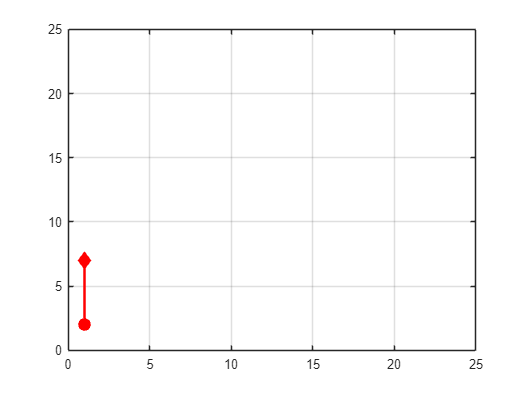

a = 1;
circle_r = 2;

% zadanie 4.2 - test metody go_forward 
vq = 1;
x0 = 1;
y0 = 2;
theta0 = pi/2;
t0 = 0;
t1 = 5;
% przez 5 sekund bedzie sie poruszal w gore 1/s z punktu (1,2) wiec
% powinien zakonczyc w punkcie (1, 7)
[x, y, theta] = go_forward(vq, x0, y0, theta0, t0, t1, a, circle_r);
path = [x;y];
plot_path(path);

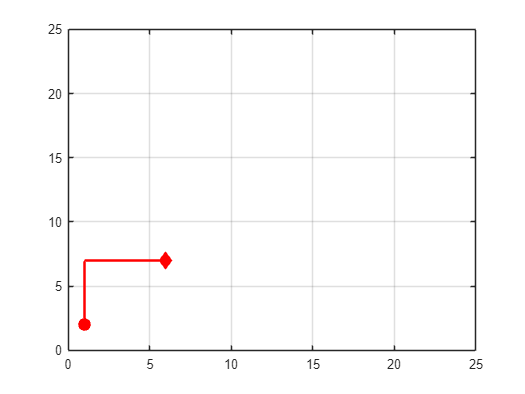

% zadanie 4.4 test
% pojedz prosto, wykrec o 90 stopni, pojedz prosto
[x, y, theta] = go_forward(vq, x0, y0, theta0, t0, t1, a, circle_r);
path = [x;y];
theta0 = theta(end);
x0 = x(end);
y0 = y(end);
t0 = t1;
t1 = 5 + t0;
angle = -pi/2;
[x, y, theta] = turn(angle, x0, y0, theta0, t0, t1, a, circle_r);
path = [path, [x;y]];
theta0 = theta(end);
x0 = x(end);
y0 = y(end);
t0 = t1;
t1 = 5 + t0;
[x, y, theta] = go_forward(vq, x0, y0, theta0, t0, t1, a, circle_r);
path = [path, [x;y]];
plot_path(path);

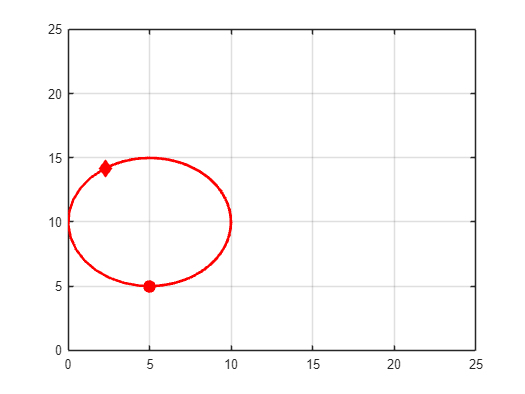


% zadanie 4.3 - test ruchu po okregu 
x0 = 5;
y0 = 5;
t0 = 0;
theta0 = 0;
t1 = 50 + t0;
r = 5;
[x, y, theta] = go_radius(vq, r, true, x0, y0, theta0, t0, t1, a, circle_r);
path = [x;y];
plot_path(path);

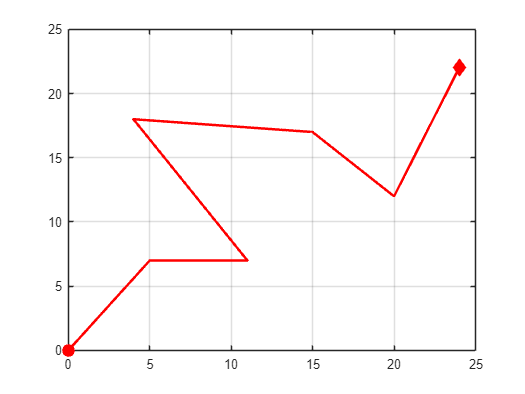

% zadanie 4.5 
% definicja sciezki
P1 = [0 0];
P2 = [5 7];
P3 = [11 7];
P4 = [4 18];
P5 = [15 17];
P6 = [20 12];
P7 = [24, 22];
path_points = [P1', P2', P3', P4', P5', P6', P7'];

% przejechanie sciezki przez robota
[x, y, theta] = travel(path_points, a, circle_r);
path = [x; y];
plot_path(path);

n = 20

n = 20

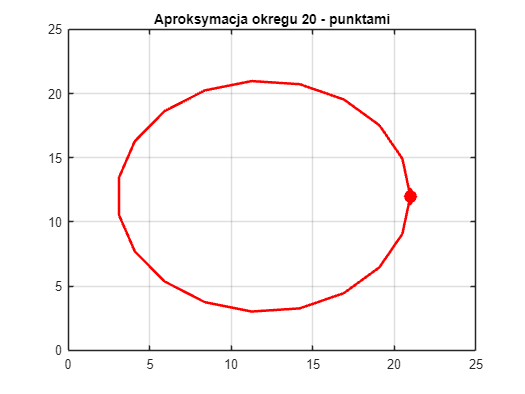

angles = linspace(0, 2*pi, 20);
radius = 9;
x2Center = 12;
y2Center = 12;
x2 = radius * cos(angles) + x2Center;
y2 = radius * sin(angles) + y2Center;

no_obstacles_path_2 = [x2;y2];

plot_path(no_obstacles_path_2);
title("Aproksymacja okregu " + n + " - punktami")

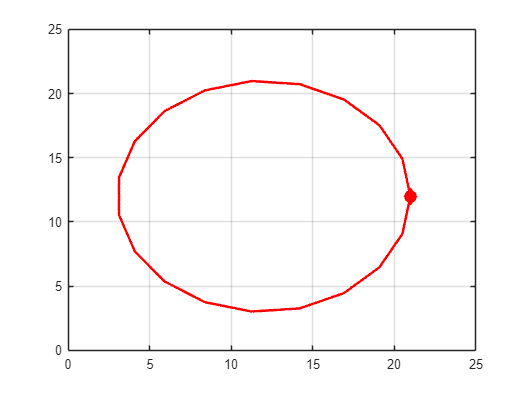

[xres, yres, thetares] = travel(no_obstacles_path_2, a, circle_r);
path = [xres; yres];
plot_path(path);

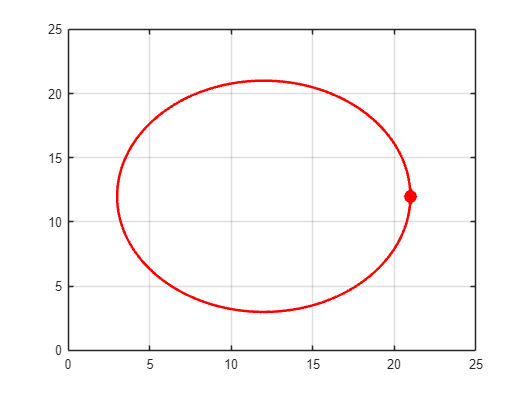

angles = linspace(0, 2*pi, 200);
radius = 9;
x2Center = 12;
y2Center = 12;
x2 = radius * cos(angles) + x2Center;
y2 = radius * sin(angles) + y2Center;

path2000 = [x2;y2];
plot_path(path2000);

[xres, yres, thetares] = travel2(path2000, a, circle_r);

points =    21.0000   20.7144   19.8758   18.5373   16.7840   14.7270   12.4970   10.2355    8.0859    6.1847    4.6526    3.5868    3.0549    3.0907    3.6919    4.8204    6.4045    8.3437   10.5150   12.7805   14.9964   17.0223   18.7293   20.0094   20.7811   21.0000
   12.0000   14.2492   16.3557   18.1857   19.6232   20.5769   20.9863   20.8253   20.1043   18.8690   17.1977   15.1966   12.9926   10.7256    8.5394    6.5730    4.9509    3.7762    3.1234    3.0339    3.5135    4.5316    6.0237    7.8951   10.0270   12.0000


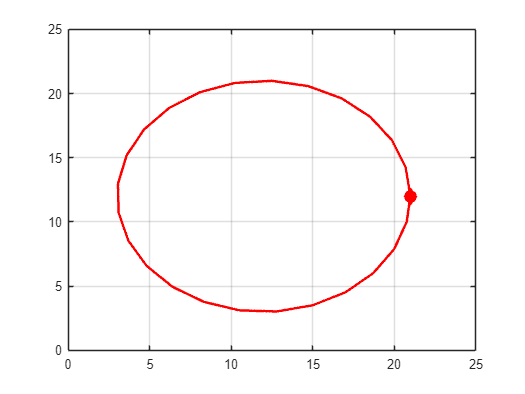

path = [xres; yres];
plot_path(path);

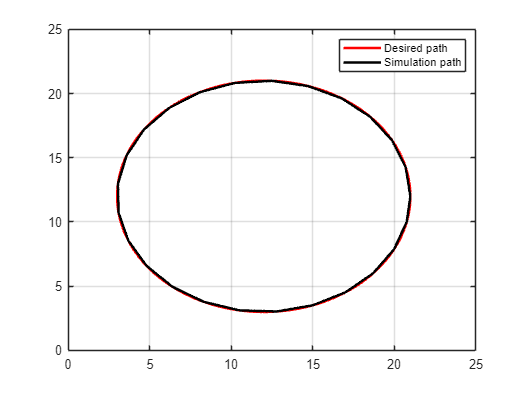

plot_paths(path2000, path);

P1 = [1 1];
P2 = [5 7];
P3 = [11 7];
P4 = [4 18];
P5 = [15 17];
P6 = [20 12];
P7 = [24, 22];

P12 = [linspace(P1(1), P2(1), 10); linspace(P1(2), P2(2), 10)];
P23 = [linspace(P2(1), P3(1), 10); linspace(P2(2), P3(2), 10)];
P34 = [linspace(P3(1), P4(1), 10); linspace(P3(2), P4(2), 10)];
P45 = [linspace(P4(1), P5(1), 10); linspace(P4(2), P5(2), 10)];
P56 = [linspace(P5(1), P6(1), 10); linspace(P5(2), P6(2), 10)];
P67 = [linspace(P6(1), P7(1), 10); linspace(P6(2), P7(2), 10)];

path2 = [P12, P23, P34, P45, P56, P67]

path2 =     1.0000    1.4444    1.8889    2.3333    2.7778    3.2222    3.6667    4.1111    4.5556    5.0000    5.0000    5.6667    6.3333    7.0000    7.6667    8.3333    9.0000    9.6667   10.3333   11.0000   11.0000   10.2222    9.4444    8.6667    7.8889    7.1111    6.3333    5.5556    4.7778    4.0000    4.0000    5.2222    6.4444    7.6667    8.8889   10.1111   11.3333   12.5556   13.7778   15.0000   15.0000   15.5556   16.1111   16.6667   17.2222   17.7778   18.3333   18.8889   19.4444   20.0000
    1.0000    1.6667    2.3333    3.0000    3.6667    4.3333    5.0000    5.6667    6.3333    7.0000    7.0000    7.0000    7.0000    7.0000    7.0000    7.0000    7.0000    7.0000    7.0000    7.0000    7.0000    8.2222    9.4444   10.6667   11.8889   13.1111   14.3333   15.5556   16.7778   18.0000   18.0000   17.8889   17.7778   17.6667   17.5556   17.4444   17.3333   17.2222   17.1111   17.0000   17.0000   16.4444   15.8889   15.3333   14.7778   14.2222   13.6667   13.1111   12.5556 

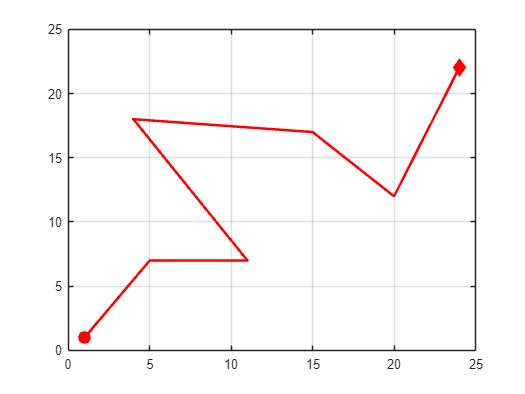

plot_path(path2);


[xres, yres, thetares] = travel2(path2, a, circle_r);

points =     1.0000    4.5556    9.0000    7.8889    6.4444   15.0000   19.4444   22.6667   24.0000
    1.0000    6.3333    7.0000   11.8889   17.7778   17.0000   12.5556   18.6667   22.0000


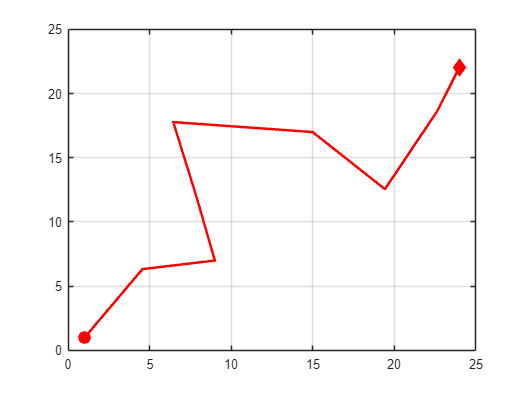

path = [xres; yres];
plot_path(path);

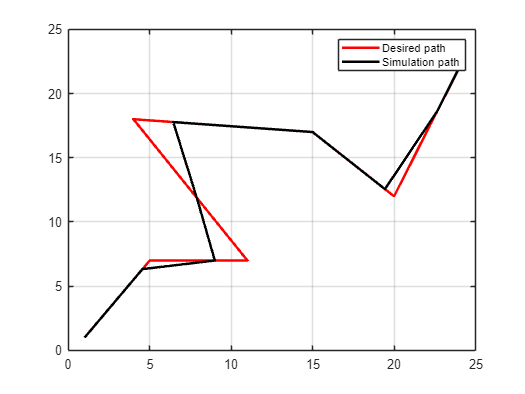

plot_paths(path2, path);

% zadanie 4.5 ale bardziej uniwersalnie

lngths = path_length(path)
lngths(192)
lngths(193)
lngths(end)
i = get_proper_length_index(lngths, 57)

% function [xres, yres, thetares] = travel_general(points, a, circle_r) % zadanie 4.5
%     n = size(points, 2);
%     T = 2;
%     t0 = 0;
%     theta0 = 0;
%     xres = [];
%     yres = [];
%     thetares = [];
%     x0 = points(1, 1);
%     y0 = points(2, 1);
% 
%     const_dist = 20;
%     sum_dist = 0;
%     lngths = path_length(path);
%     i = get_proper_length_index(lngths);
%     while i < n
%         x2 = points(1, i);
%         y2 = points(2, i);
% 
%         desir_theta = atan2(y2 - y0, x2 - x0);
%         t1 = t0 + T;
%         % obrot
%         [x, y, theta] = turn(desir_theta - theta0, x0, y0, theta0, t0, t1, a, circle_r);
%         xres = [xres, x];
%         yres = [yres, y];
%         thetares = [thetares, theta];
%         theta0 = theta(end);
%         x0 = x(end);
%         y0 = y(end);
% 
%         s = (y2 - y0) ^2 + (x2 - x0) ^2;
%         s = sqrt(s);
% 
%         vq = s / T;
%         t0 = t1;
%         t1 = t0 + T;
%         % jedz w strone celu
%         [x, y, theta] = go_forward(vq, x0, y0, theta0, t0, t1, a, circle_r);
% 
%         xres = [xres, x];
%         yres = [yres, y];
%         thetares = [thetares, theta];
% 
%         theta0 = theta(end);
%         x0 = x(end);
%         y0 = y(end);
%         t0 = t1;
%     end
% end
% 
% function lngth = path_length(path)
%     lngth = [0];
%     n = size(path,2);
%     for i = 1:n-1
%         x1 = path(1,i);
%         x2 = path(1,i+1);
%         y1 = path(2,i);
%         y2 = path(2,i+1);
%         lngth = [lngth, lngth(end) + sqrt((y2 - y1) ^ 2 + (x2 - x1)^2)];
%     end
% end
% 
% function [mid] = get_proper_length_index(lngths, path_size)
%     n = size(lngths,2);
% 
%     r = n;
%     l = 1;
%     mid = r;
%     if path_size > lngths(end)
%         mid = n;
%         return;
%     end
%     while r - 1 > l
%         mid = fix((r + l) / 2);
%         if lngths(mid) > path_size
%             r = mid;
%         else
%             l = mid;
%         end
%     end
% 
% end

function [xres, yres, thetares] = travel2(points, a, circle_r) % zadanie 4.5
    points = [points(:, 1: 8: end), points(:, end)]
    n = size(points, 2);
    T = 2;
    t0 = 0;
    theta0 = 0;
    xres = [];
    yres = [];
    thetares = [];
    x0 = points(1, 1);
    y0 = points(2, 1);
    for i = 2:n
        x2 = points(1, i);
        y2 = points(2, i);

        desir_theta = atan2(y2 - y0, x2 - x0);
        t1 = t0 + T;
        % obrot
        [x, y, theta] = turn(desir_theta - theta0, x0, y0, theta0, t0, t1, a, circle_r);
        xres = [xres, x];
        yres = [yres, y];
        thetares = [thetares, theta];
        theta0 = theta(end);
        x0 = x(end);
        y0 = y(end);
        
        s = (y2 - y0) ^2 + (x2 - x0) ^2;
        s = sqrt(s);

        vq = s / T;
        t0 = t1;
        t1 = t0 + T;
        % jedz w strone celu
        [x, y, theta] = go_forward(vq, x0, y0, theta0, t0, t1, a, circle_r);
        
        xres = [xres, x];
        yres = [yres, y];
        thetares = [thetares, theta];

        theta0 = theta(end);
        x0 = x(end);
        y0 = y(end);
        t0 = t1;
    end
end
function [xres, yres, thetares] = travel(points, a, circle_r) % zadanie 4.5
    n = size(points, 2);
    T = 2;
    t0 = 0;
    theta0 = 0;
    xres = [];
    yres = [];
    thetares = [];
    x0 = points(1, 1);
    y0 = points(2, 1);
    for i = 2:n
        x2 = points(1, i);
        y2 = points(2, i);

        desir_theta = atan2(y2 - y0, x2 - x0);
        t1 = t0 + T;
        % obrot
        [x, y, theta] = turn(desir_theta - theta0, x0, y0, theta0, t0, t1, a, circle_r);
        xres = [xres, x];
        yres = [yres, y];
        thetares = [thetares, theta];
        theta0 = theta(end);
        x0 = x(end);
        y0 = y(end);
        
        s = (y2 - y0) ^2 + (x2 - x0) ^2;
        s = sqrt(s);

        vq = s / T;
        t0 = t1;
        t1 = t0 + T;
        % jedz w strone celu
        [x, y, theta] = go_forward(vq, x0, y0, theta0, t0, t1, a, circle_r);
        
        xres = [xres, x];
        yres = [yres, y];
        thetares = [thetares, theta];

        theta0 = theta(end);
        x0 = x(end);
        y0 = y(end);
        t0 = t1;
    end
end


function [x, y, theta] = go_forward(vq, x0, y0, theta0, t0, t1, a, circle_r) % zadanie 4.2
    T = t1 - t0;
    % ustawienie parametrow rozmiaru robota
    set_param('model/Constant', 'Value', num2str(a)); 
    set_param('model/Constant1', 'Value', num2str(circle_r));

    % ustawienie wartosci poczatkowych
    set_param('model/Constant4', 'Value', num2str(theta0)); 
    set_param('model/Constant2', 'Value', num2str(x0)); 
    set_param('model/Constant3', 'Value', num2str(y0)); 

    % obliczenie predkosci
    w = vq / circle_r;

    % ustawienie predkosci na ruch po prostej
    set_param('model/Constant5', 'Value', num2str(w)); 
    set_param('model/Constant6', 'Value', num2str(w)); 

    simOut = sim('model', 'StopTime', num2str(T));
    
    % zwrocenie wartosci
    x = simOut.x';
    y = simOut.y';
    theta = simOut.theta';
end

% zadanie 4.3
% dir = True prawe kolo dominuje
function [x, y, theta] = go_radius(vq, r, dir, x0, y0, theta0, t0, t1, a, circle_r)
    T = t1 - t0;
    
    % ustawienie parametrow rozmiaru robota
    set_param('model/Constant', 'Value', num2str(a)); 
    set_param('model/Constant1', 'Value', num2str(circle_r));
    
    % ustawienie wartosci poczatkowych
    set_param('model/Constant4', 'Value', num2str(theta0)); 
    set_param('model/Constant2', 'Value', num2str(x0)); 
    set_param('model/Constant3', 'Value', num2str(y0)); 

    % obliczenie predkosci na kolo
    if dir == true
        vr = vq * (r + a) / r;
        vl = vq * (r - a) / r;
    else
        vl = vq * (r + a) / r;
        vr = vq * (r - a) / r;
    end
    wl =  vl / circle_r;
    wr =  vr / circle_r;

    % ustawienie predkosci na ruch po okregu
    set_param('model/Constant5', 'Value', num2str(wr)); 
    set_param('model/Constant6', 'Value', num2str(wl)); 

    simOut = sim('model', 'StopTime', num2str(T));
    
    % zwrocenie wartosci
    x = simOut.x';
    y = simOut.y';
    theta = simOut.theta';
end

% zadanie 4.4
% kat podawany w radianach
function [x, y, theta] = turn(angle, x0, y0, theta0, t0, t1, a, circle_r)
    T = t1 - t0;
    
    % ustawienie parametrow rozmiaru robota
    set_param('model/Constant', 'Value', num2str(a)); 
    set_param('model/Constant1', 'Value', num2str(circle_r));
    
    % ustawienie wartosci poczatkowych
    set_param('model/Constant4', 'Value', num2str(theta0)); 
    set_param('model/Constant2', 'Value', num2str(x0)); 
    set_param('model/Constant3', 'Value', num2str(y0)); 


    wr = angle / ( 2 * T);
    wl = - wr;
    % ustawienie predkosci
    set_param('model/Constant5', 'Value', num2str(wr)); 
    set_param('model/Constant6', 'Value', num2str(wl)); 

    simOut = sim('model', 'StopTime', num2str(T));
    
    % zwrocenie wartosci
    x = simOut.x';
    y = simOut.y';
    theta = simOut.theta';
end

function plot_path(path)
    x = path(1, :);
    y = path(2, :);
    figure;
    plot(x, y, 'r', 'LineWidth', 2);
    hold on;
    scatter(x(1), y(1), 100, 'r', 'filled'); 
    scatter(x(end), y(end), 100, 'r', 'd', 'filled'); 
    hold off;
    grid on;
    axis([0, 25, 0, 25])
end

function plot_paths(desir_path, simulation_path)
    x = desir_path(1, :);
    y = desir_path(2, :);
    fig = figure;
    plot(x, y, 'r', 'LineWidth', 2, 'DisplayName',"Desired path");
    hold on;
    % scatter(x(1), y(1), 100, 'r', 'filled'); 
    % scatter(x(end), y(end), 100, 'r', 'd', 'filled'); 

    x = simulation_path(1, :);
    y = simulation_path(2, :);

    plot(x, y, 'k', 'LineWidth', 2, 'DisplayName','Simulation path');

    % scatter(x(1), y(1), 100, 'k', 'filled'); 
    % scatter(x(end), y(end), 100, 'k', 'd', 'filled'); 
    hold off;
    % axis off;
    grid on;
    axis([0, 25, 0, 25])
    legend;
    % axis([-25 25 -25 25]);
end